# Spotting Swing Model

%[theta d a alpha sigma offset]
% theta [rad] angle of joint
% d length of prismatic componet
% a length of link
% alpha [rad] link twist angle
% sigma: prismatic == 1 and revolute == 0
% offset

link0A = Link( [ deg2rad( 21.0375 ), 0, 6.9642, 0, 0, 0], 'standard' );
link0A.qlim = pi/180 * [21.0375-5 21.0375+5];

link1 = Link( [ deg2rad(74.311), 0, 17.917, 0, 0, 0], 'standard' );
link1.qlim = pi/180 * [74.311-5 74.311+5];

link1 = Link( [ deg2rad(0), 0, 17.917, 0, 0, 0], 'standard' );
link1.qlim = pi/180 * [0-5 0+5];

link2 = Link( [ deg2rad(0), 0, 13.75, 0, 0, 0], 'standard' );
link2.qlim = pi/180 * [-5 5];

%used to orientaion correctly
link2A = Link( [ 0, 0, 0, deg2rad(90), 0, 0], 'standard');
link2A.qlim = pi/180 * [-5 5];

link3 = Link( [           deg2rad(0), 0,     0, 0, 1, 0], 'standard' );
link3.qlim = [0 4.75];

modelMasterX = SerialLink( [link0A, link1, link2, link2A, link3], 'name', 'masterX')

 
modelMasterX = 
 
masterX:: 5 axis, RRRRP, stdDH, slowRNE                          
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|     6.9642|          0|          0|
|  2|         q2|          0|     17.917|          0|          0|
|  3|         q3|          0|      13.75|          0|          0|
|  4|         q4|          0|          0|     1.5708|          0|
|  5|          0|         q5|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


%inputs forward kinematics
spottingSWGCylinderExtension = 4.75/2 %limit is 0 to 4.75

spottingSWGCylinderExtension = 2.3750

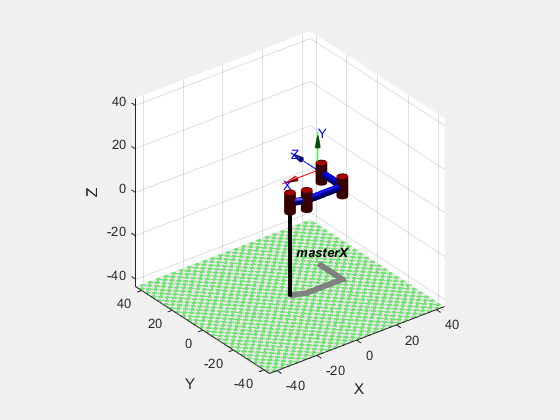

Tmaster = [deg2rad( -21.0375), deg2rad(21.0375), deg2rad(90), deg2rad(90), spottingSWGCylinderExtension ];
modelMasterX.plot(Tmaster)


%input inverse kinematic
masterHoleX = 8.842

masterHoleX = 8.8420

%angles look to be between 10 and -10 degrees, inclinometers are not set up to report negative angles so it will be in range of (180, 360)
gunAngle = 82; 
gunHeight = 6.9642 * sin( deg2rad( gunAngle - 62 ) )%21.0375 + gunAngle ) )

gunHeight = 2.3819

gunXoffset = 6.9642 * cos( deg2rad( gunAngle - 62 ))%21.0375 + gunAngle ) )

gunXoffset = 6.5442

%angles look to be between 10 and -10 degrees, inclinometers are not set up to report negative angles so it will be in range of (180, 360)
guidewheelAngle = 2.5;
guidewheelHeight = 28.896 * sin( deg2rad( 90+ guidewheelAngle )) %17.917 * cos( deg2rad( guidewheelAngle ))%+ 88.6659) )

guidewheelHeight = 28.8685

guidewheelxoffset = 28.896 * cos( deg2rad( 90 + guidewheelAngle)) %17.917 * sin( deg2rad( guidewheelAngle ))%+ 88.6659) )

guidewheelxoffset = -1.2604

height = gunHeight + guidewheelHeight

height = 31.2504

x = 38.189 * cos( deg2rad( 89.5304 + gunAngle ) )

x = -37.7725

xoffset = 17.917 * sin( deg2rad( guidewheelAngle ) ) + 6.9642 * sin( deg2rad( 21.0375 + gunAngle ) )

xoffset = 7.5662

gunX = 29.508 * cos( deg2rad( 88.6659 + gunAngle ) )% + 14 * cos( deg2rad( gunAngle ) )

gunX = -29.1173

spottingFWDCylinderExtension = masterHoleX - gunXoffset - guidewheelxoffset + 13.75 -13.92

spottingFWDCylinderExtension = 3.3882

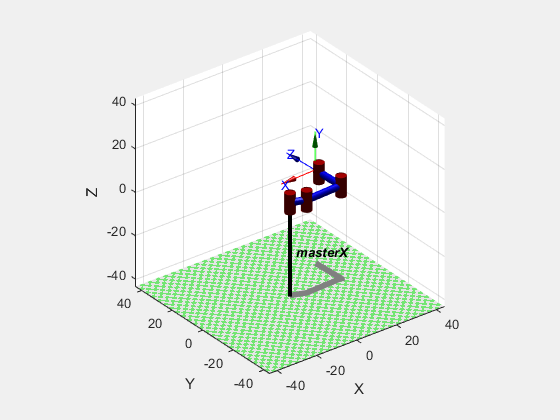

%spottingFWDCylinderExtension = masterHoleX - link2.a - xoffset + x + 12
%spottingSWGCylinderExtension = sqrt(masterHoleX * masterHoleX + height * height) - link2.a - xoffset + x
Tmaster = [ deg2rad( 62 - gunAngle ), deg2rad(guidewheelAngle + (gunAngle - 62) ), deg2rad(90), deg2rad(90), spottingSWGCylinderExtension ];
modelMasterX.plot(Tmaster)

# Pattern Swing Model

%L1 = Link ([0 l1 0 pi/2],'standard');
%L1.isrevolute
%L1.qlim =  pi/180*[-180 18

%[theta d a alpha sigma offset]
%sigma == 1, prismatic
%sigma == 0, revolute
link1 = Link( [ deg2rad(0), 0, 32.75, 0, 0, 0], 'standard' );
link1.qlim = pi/180 * [-60 60];

link2 = Link( [ deg2rad(-90), 0, 20.25, 0, 0, 0], 'standard' );
link2.qlim = pi/180 * [-95 85];

%used to orientaion correctly
link2A = Link( [0, 0, 0, deg2rad(90), 0, 0], 'standard');
link2A.qlim = pi/180 * [-5 5];

%39.486
link3 = Link( [ deg2rad( 0), 0, 0, deg2rad(-90), 1, 0], 'standard' );
link3.qlim = [ 0 9.5];

link4 = Link( [ deg2rad(0), 0, 32.75, 0, 0, 0], 'standard' );
link4.qlim = pi/180 * [ -60 60];

%modelSlaveX = SerialLink( [link1, link2, link2A, link3 ], 'name', 'slaveX')
modelSlaveX = SerialLink( [link1, link2, link2A, link3, link4], 'name', 'slaveX')

 
modelSlaveX = 
 
slaveX:: 5 axis, RRRPR, stdDH, slowRNE                           
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|      32.75|          0|          0|
|  2|         q2|          0|      20.25|          0|          0|
|  3|         q3|          0|          0|     1.5708|          0|
|  4|          0|         q4|          0|    -1.5708|          0|
|  5|         q5|          0|      32.75|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 



%inputs forward kinematics
patternSWGCylinderExtension = 9.5/2 %limit is 0 to 9.5

patternSWGCylinderExtension = 4.7500

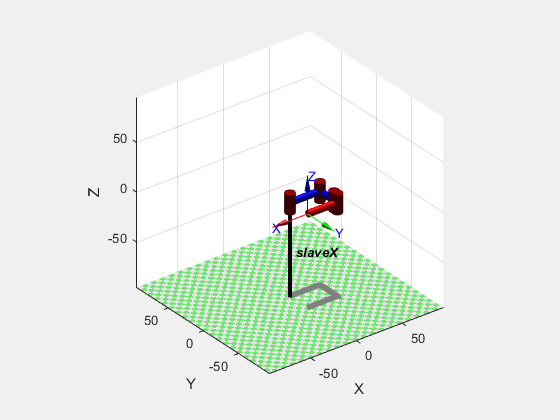

Tslave = [ deg2rad( 0 ), deg2rad(-90), deg2rad(90), patternSWGCylinderExtension, deg2rad( 180 )];
modelSlaveX.plot(Tslave)

%input inverse kinematic
slaveHoleX = 17.866

slaveHoleX = 17.8660

version = 2;
height = 38.188 * cos( deg2rad( 70 ))

height = 13.0611

if version == 1
    patternSWGCylinderExtension = sqrt( slaveHoleX * slaveHoleX + height*height ) - link2.a
else
    carriageToGun = 7.061;
    carriageToSpottingCylinder = 0.313;
    patternSWGCylinderExtension = slaveHoleX - link2.a - masterHoleX + carriageToGun+(carriageToGun-carriageToSpottingCylinder)
end

patternSWGCylinderExtension = 2.5830

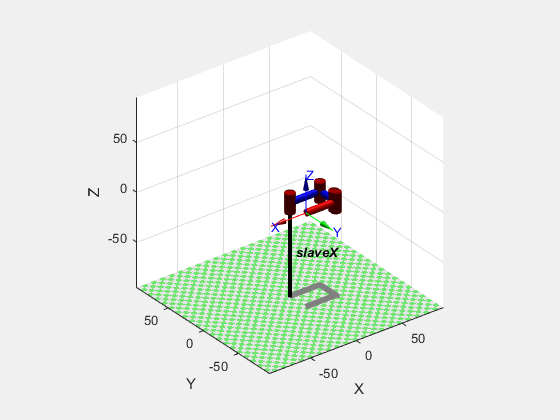


Tslave = [ deg2rad( 0 ), deg2rad(-90), deg2rad(90), patternSWGCylinderExtension, deg2rad( 180 )];
modelSlaveX.plot(Tslave)